# Exercici 2 de laboratori

1. El primer que farem és llegir les imatges i les convertim a double

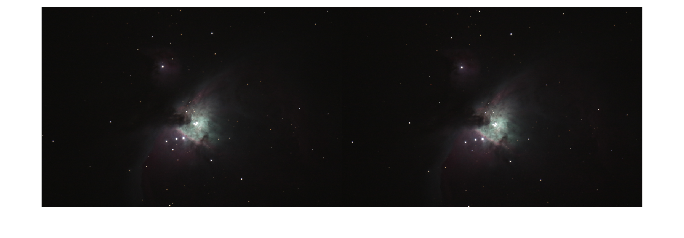

A = double(imread('_MG_7735.jpg'))/255;
B = double(imread('_MG_7737.jpg'))/255;
montage({A,B})

2. Comprovem que passaria si superposem les imatges directament. Per veure-ho, restem les imatges píxel a píxel i el resultat el re-escalem entre 0-1

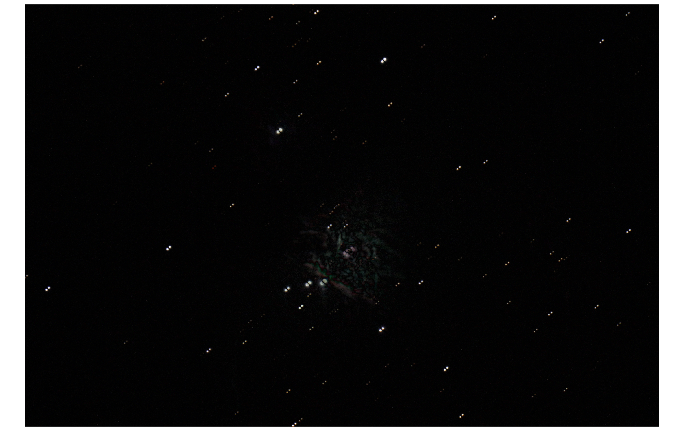

DIF = abs(A-B); % imatge diferencia
maxim = max(DIF(:));
DIF = DIF/maxim; % dividim pel seu valor màxim
imshow(DIF)

3. Traslladem per codi la imatge B 20 píxels en diagonal i observem que les imatges s’ajusten prou bé

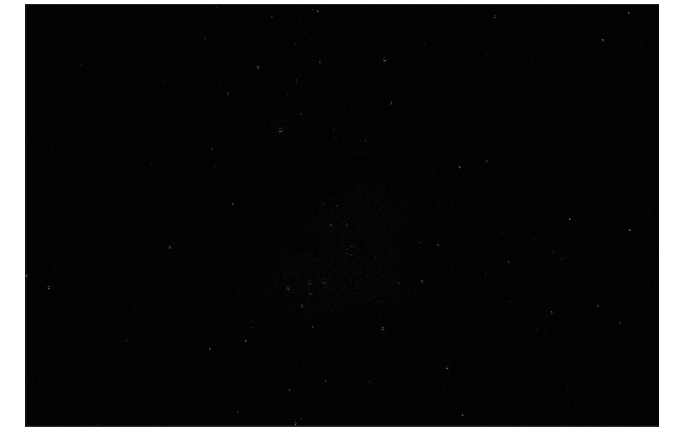

Bd = imtranslate(B,[20, -20]);
DIF = abs(A-Bd);
maxim = max(DIF(:));
DIF = DIF/maxim;
imshow(DIF)

4. Ara ja podem sumar les dues imatge A i Bd per obtenir una nova imatge “millorada”

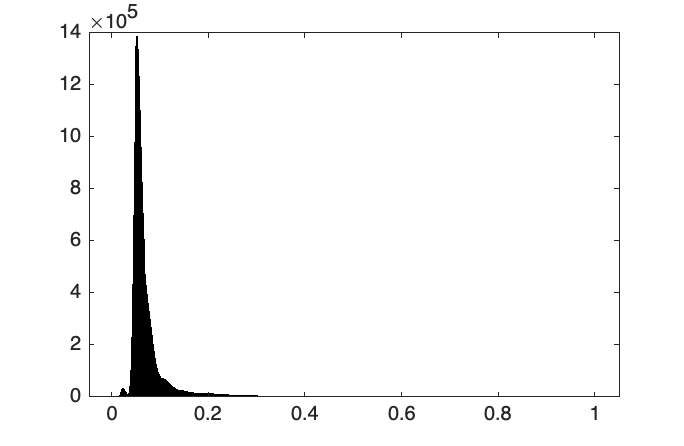

I = (A+Bd)/2;
HSV = rgb2hsv(I);
V = HSV(:,:,3);
histogram(V)

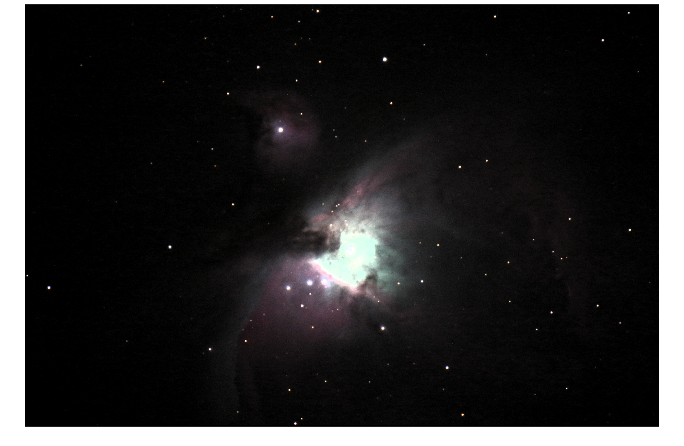

NV = imadjust(V,[0.05,0.5]);
HSV(:,:,3) = NV;
Ac = hsv2rgb(HSV);
imshow(Ac);

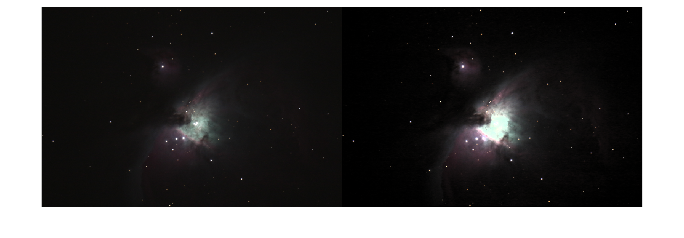

montage ({A,Ac});